clc; close all; clear;

inDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/MARZ/Example Data/UXI PHC/');
  

# UXI camera 1

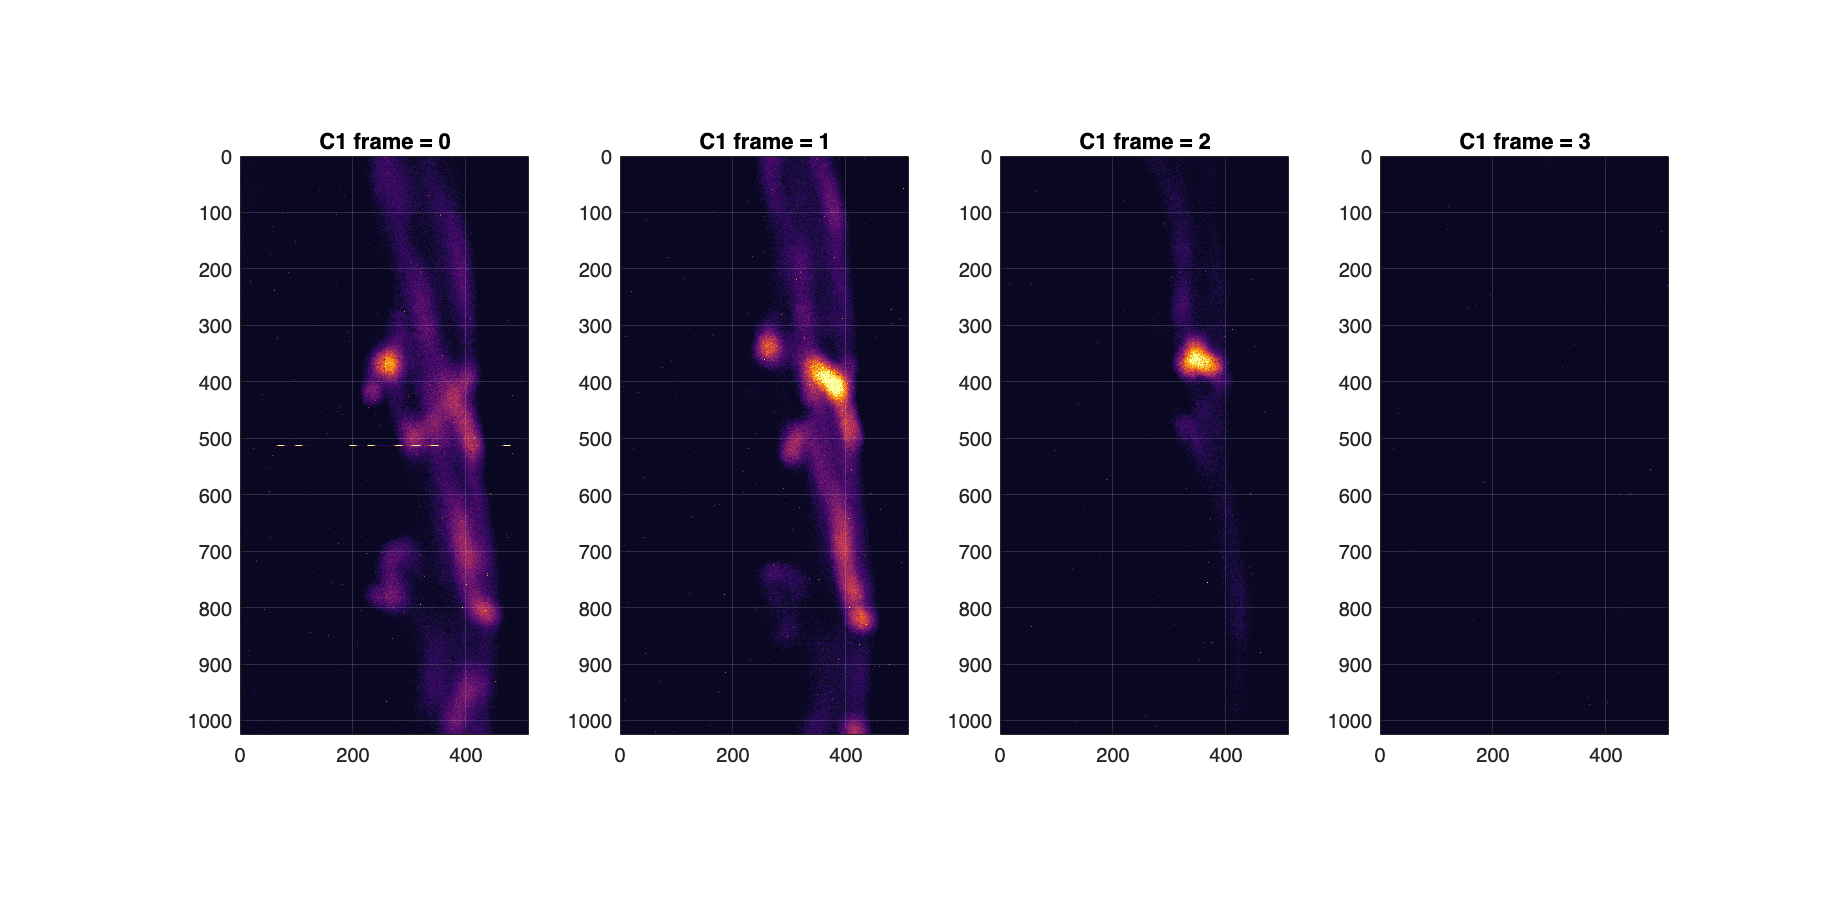


camera = 1;
figure
for ii = 0:3
subplot(1,4,ii+1)
sub_img = loadUXI(inDir,camera,ii);
imagesc(sub_img);
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,30])
[m,n] = size(sub_img);
xlim([0,n]); ylim([0,m]);
title(['C' num2str(camera) ' frame = ' num2str(ii)]); 
end
set(gcf,'Position',[0 0 1800 900])

# UXI camera 2

camera = 2;
figure
for ii = 0:3
subplot(1,4,ii+1)
sub_img = loadUXI(inDir,camera,ii);
imagesc(sub_img);
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,30])
[m,n] = size(sub_img);
xlim([0,n]); ylim([0,m]);
title(['C' num2str(camera) ' frame = ' num2str(ii)]); 
end
set(gcf,'Position',[0 0 1800 900])


# Sort according to time

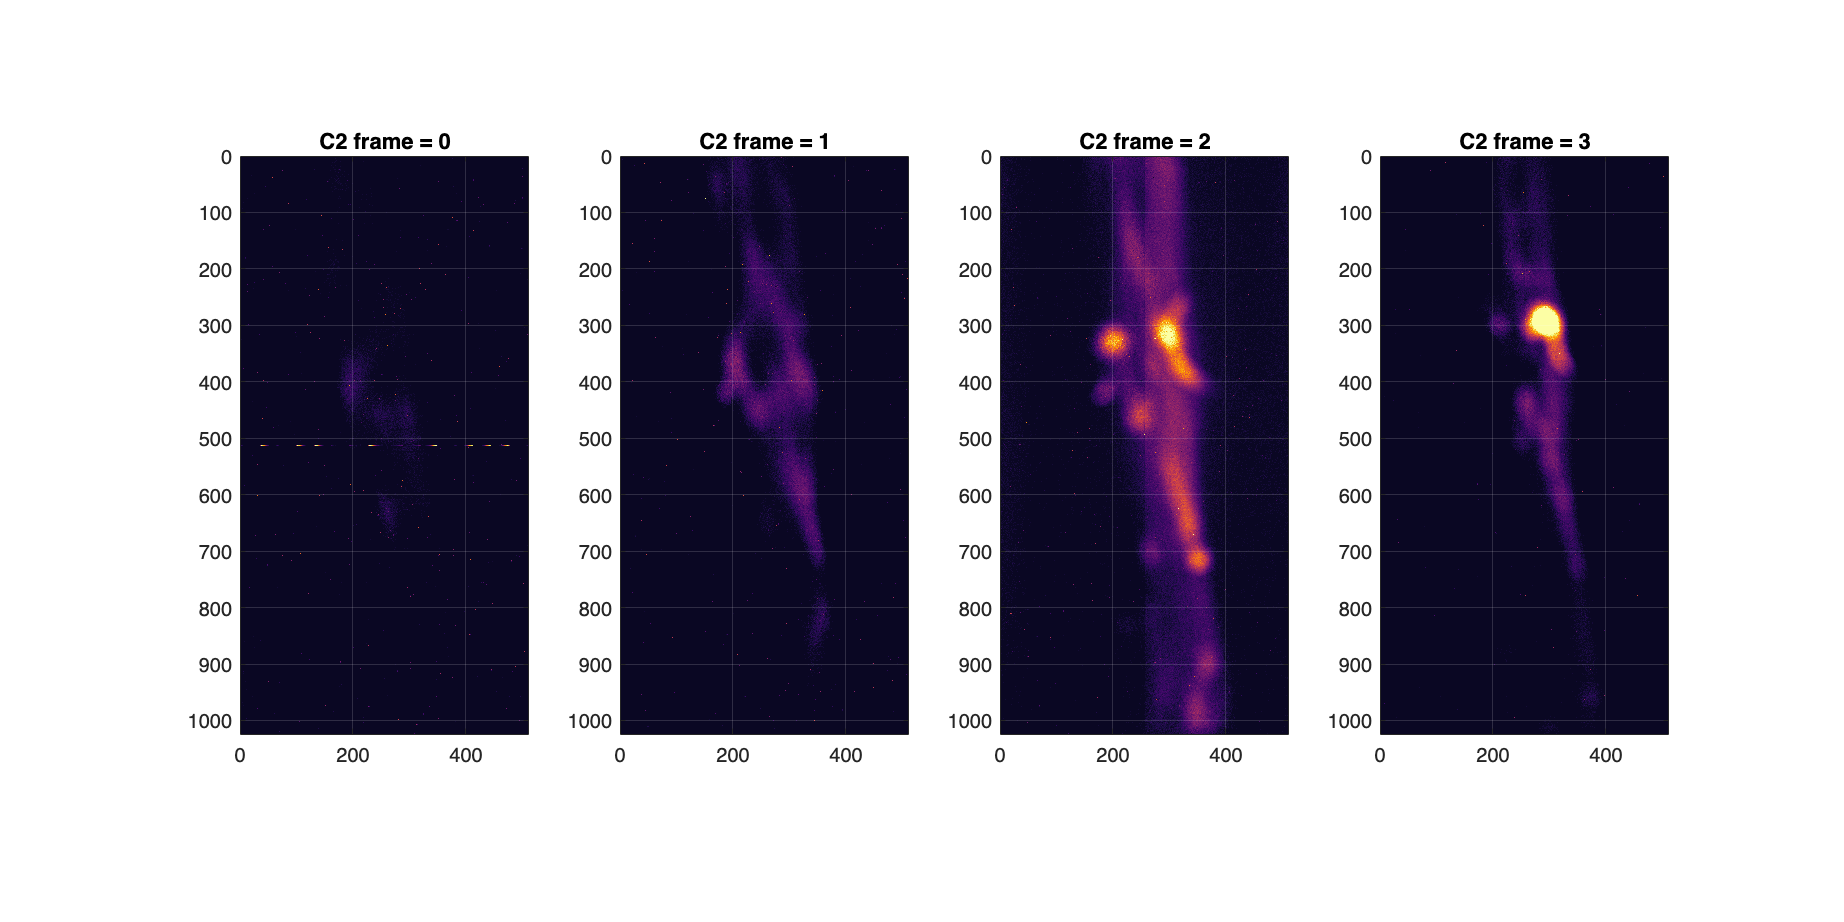

[data,~,~] = xlsread("marz3_uxi.xlsx");

t = data(:,1); camera = data(:,2); frame = data(:,3);

figure
for ii = 1:length(t)
    subplot(1,numel(t),ii)
    sub_img = loadUXI(inDir,camera(ii),frame(ii));
    imagesc(sub_img); colormap(inferno());
    grid on; ax = gca; ax.GridColor = [1,1,1];  % [R, G, B]
    axis equal; 
    [m,n] = size(sub_img);
    xlim([0,n]); ylim([0,m]);
    title(['C' num2str(camera(ii)) ' ' num2str(t(ii)) ' ns'],fontsize=18); 
    caxis([-2,25])
    set(gca,'XTickLabel',[]);
    set(gca,'YTickLabel',[]);
end
set(gcf,'Position',[0 0 1800 900])


# Export

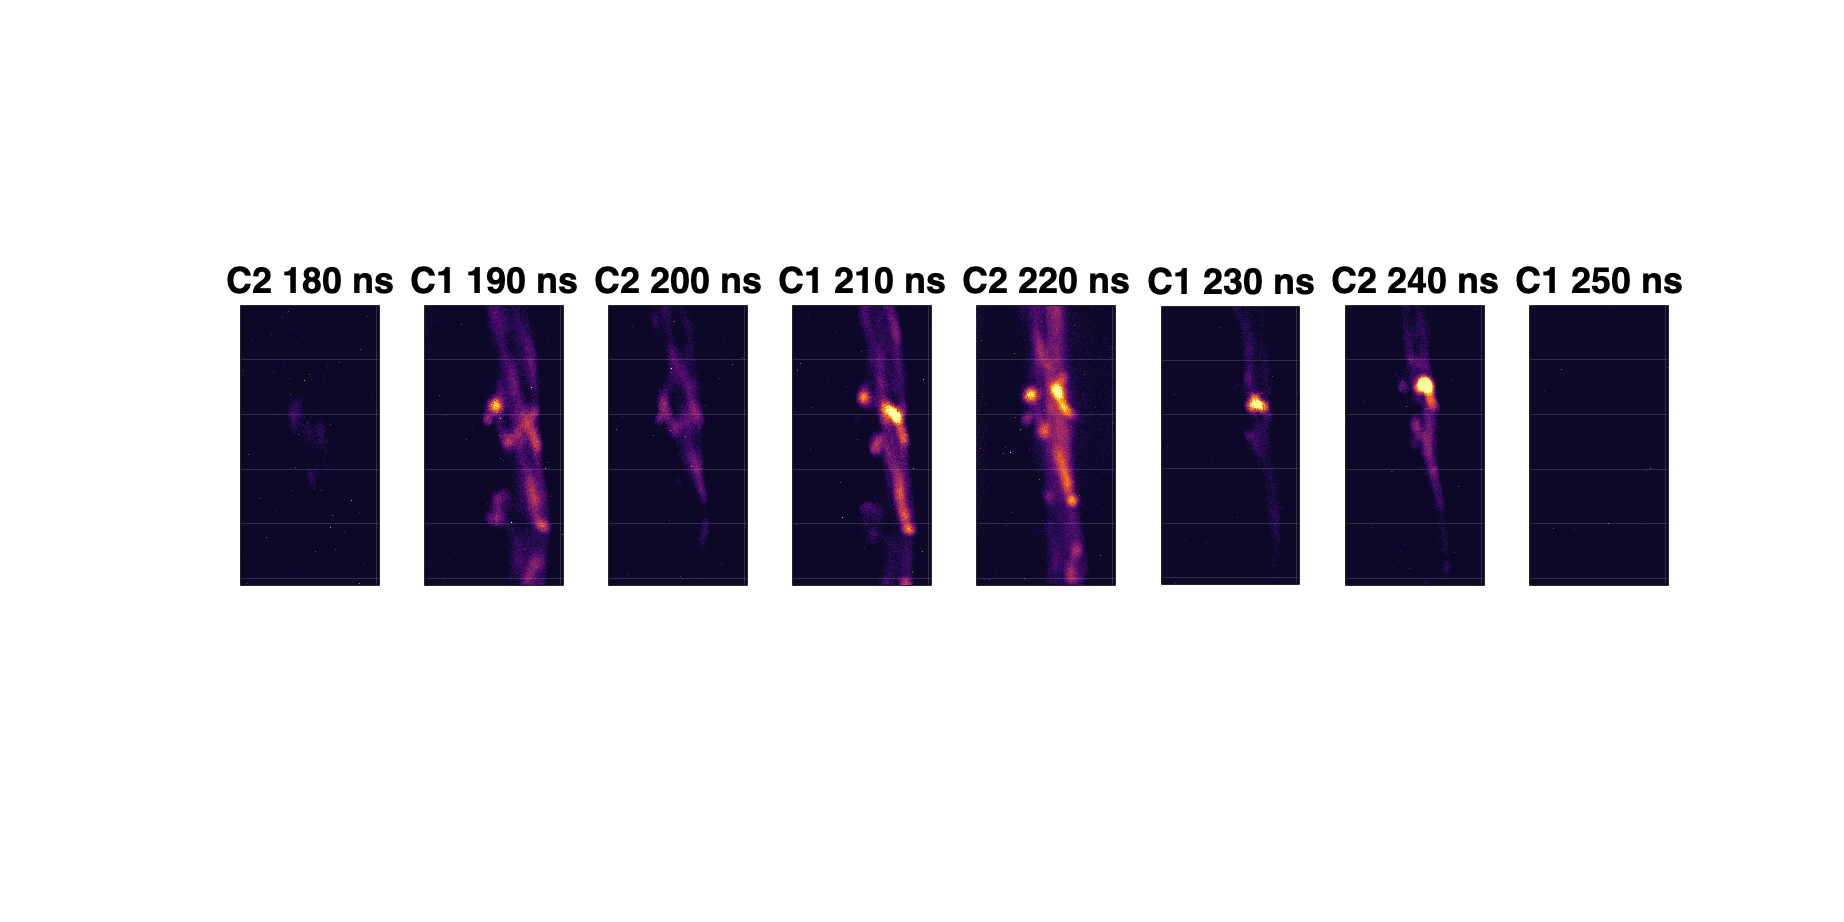

[data,~,~] = xlsread("marz3_uxi.xlsx");

t = data(:,1); camera = data(:,2); frame = data(:,3);

figure
for ii = 1:length(t)
    sub_img = loadUXI(inDir,camera(ii),frame(ii));
    imagesc(sub_img); colormap(inferno());
    grid on; ax = gca; ax.GridColor = [1,1,1];  % [R, G, B]
    axis equal; 
    [m,n] = size(sub_img);
    xlim([0,n]); ylim([0,m]);
    title(['C' num2str(camera(ii)) ' ' num2str(t(ii)) ' ns'],fontsize=24); 
    caxis([-2,20])
    set(gca,'XTickLabel',[]);
    set(gca,'YTickLabel',[]);
    set(gcf,'Position',[0 0 200 400])
    saveas(gcf,['UXIimages/t=' num2str(t(ii)) '.png']);
end